% 牽引物の慣性モーメント

%平面の重心
x1 = [-2 -1.5 0 1.5 1 0];
y1 = [-1 1/2 1 1/2 -1/2 -1];
z1 = ones(1,6);
p = [x1;y1;z1];
polyin = polyshape(x1,y1);
[x,y] = centroid(polyin)

x = -0.2949

y = -0.0769

G = [x;y;0.5];
rho = sum((p-G).^2)

rho =     4.0095    2.0352    1.4967    3.8044    2.1057    1.1890


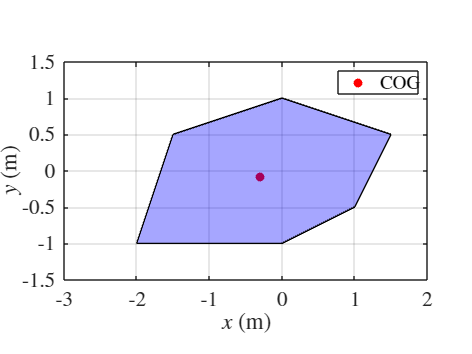


plot(x,y,"r.","MarkerSize",20)
hold on
plot(polyin,"FaceColor","b")
daspect([1,1,1])
xlabel('$x$ (m)','Interpreter','latex')
ylabel('$y$ (m)','Interpreter','latex')
legend("COG",'NumColumns',1,'Interpreter','latex')
set(gca,'FontSize',16,"TickLabelInterpreter","latex")
grid on
% grid minor
hold off

syms xx yy zz real positive
syms a b c h v m
%z
Isqu = m*(a^2+b^2)/3;
r1=2;
r2=2;
r3=1;
V = r1*r2*r3-3*(r1/2*r2/4)*r3/2

V = 3.2500

rho = m/V;
yMinRange = -(y1(3)-y1(4))*xx/x1(4) + y1(3);
f = xx^2+yy^2;
fy = int(f,yy,[yMinRange,y1(3)]);
Itri_z = int(fy,xx,[0,x1(4)])*rho;

Iz = Isqu - 3*Itri_z + m*G(1:2)'*G(1:2);
Iz = double(subs(Iz,[a,b,m],[1,1,1.2]))

Iz = 0.4735


%y
xMinRange = (yy-h)*c/(v-h);
f = xx^2+zz^2;
fx = int(f,xx,[xMinRange,c]);
fxz = int(fx,zz,[-a,a]);
fxzy = int(fxz,yy,[v,h]);
Itri_y = fxzy*rho;

Iy = Isqu - 3*Itri_y + m*G(2:3)'*G(2:3);
Iy = double(subs(Iy,[a,b,c,h,v,m],[1,0.5,1,1,0.5,1.2]))

Iy = 0.3434

%x
zMinRange = (h-v)*xx/c + v;
f = yy^2+zz^2;
fy = int(f,yy,[zMinRange,h]);
fyz = int(fy,zz,[-a,a]);
fyzx = int(fyz,xx,[0,c]);
Itri_x = fyzx*rho;

Ix = Isqu - 3*Itri_x + m*[G(1);G(3)]'*[G(1);G(3)];
Ix = double(subs(Ix,[a,b,c,h,v,m],[1,0.5,1,1,0.5,1.2]))

Ix = 0.2262

MinRange = b*yy/a;
f = yy^2+xx^2;
fx = int(f,xx,[-MinRange,MinRange]);
fxy = int(fx,yy,[0,a]);
Vp = double(subs(6*a*b,[a,b],[sqrt(3)/2,1/2]))

Vp = 2.5981

rho = m/(6*a*b)

$$rho = \frac{m}{6\,a\,b}$$

II = fxy*rho

$$II = \frac{m\,\left(3\,a^{2}+b^{2}\right)}{36}$$

subs(II,[a,b,m],[sqrt(3)/2,1/2,1.2])*6

$$ans = \frac{1}{2}$$